clear;
close all;

syms P1 P2 F;

F0 = 830; % lbs
alpha = 0.543 % radians

alpha = 0.5430

y = .5; % inches
a = 1.6; % inches

eqn1 = F - F0*sin(alpha) == 0;
eqn2 = P1 + P2 - F0*cos(alpha) == 0;
eqn3 = P2 * a/2 - P1 * a/2 + F0*sin(alpha) * y;

solutions = vpasolve([eqn1, eqn2, eqn3], [P1, P2, F]);

P1_sol = solutions.P1

$$P1\_sol = 489.32822895571968047079280950129$$

P2_sol = solutions.P2

$$P2\_sol = 221.28657633781295999142457731068$$

F_sol = solutions.F

$$F\_sol = 428.86664418865075276698917150497$$

**POTTING RADIUS CALCULATOR FOR SINGLE INSERT**

clear;
close all;
% MAXIMUM INSERT LOADCASE
Title = 'Test';
%P_kN = 15;
P = 0; % normal (tensile or compressive) force (lb)
Q = 400; % shear (in-plane) force (lb)
M = 48;    % bending moment (lb-in) - should be resolved into shear force prior to calculation
T = 0;    % torsional moment (lb-in)


% CORE PROPERTIES - 6.1 pcf hexcel core
Gc = 13667; % effective shear modulus (psi)
Sc = 0.125; % core cell size (in)
c = 0.5; % core height (in)
t0 = 0.0015; % core foil thickness (in)

Twcrit_min = 272; % minimum core shear strength (psi)
Twcrit_typ = 340; % typical core shear strength (psi)
%}

%{
% CORE PROPERTIES - 5.7 pcf hexcel core
Gc = 12833; % effective shear modulus (psi)
Sc = 3/16; % core cell size (in)
c = 0.75; % core height (in)
t0 = 0.002; % core foil thickness (in)
%Twcrit = 244; % minimum core shear strength (psi)
Twcrit = 300; % typical core shear strength (psi)
%}

T0crit = 24000; % core material shear strength (psi) - Al 5052-H38 per ASM Matweb (Hexcel is H39)

% FACE SHEET PROPERTIES - from Aidan's, validate with SES
f = 0.055; % face sheet thickness (in)
vf = 0.3; % poisson's ratio = sqrt(vxy*vyx)
Ef = 5.77*10^6; % young's modulus (psi) = sqrt(Ex*Ey)
Sigma_fy = 14000; % interlaminar shear strength (psi)

% DEFINE INSERT RADIUS RANGE
bi = linspace(0.15,5,5000); % insert radius (in)
bp = bi+0.35*Sc; % real potting radius (in)

beta = c/f; % [C.2-9]
alpha = 1/f * sqrt(Gc/Ef*12*(1-vf^2)*(1+beta/2)); % [C.2-10]
t_nom = P ./ 2*pi.*bp.*c; % [C.2-13]
%K = bp./r * 
%t_r = t_nom .* C_star .* K;
C_star = beta / (beta+1); % [C.2-14];

r_tmax = bp./(1-exp(-.931714.*(alpha.*bp).^.262866)); % [C.2-16]
K_max = bp./r_tmax.*(1-sqrt(r_tmax./bp).*exp(alpha.*(bp-r_tmax))); % [C.2-6]

Pcrit_typ = (2.*pi.*bp.*c.*Twcrit_typ)./(C_star.*K_max); % [C.2-17] valid for tensile and compressive loads
Pcrit_min = (2.*pi.*bp.*c.*Twcrit_min)./(C_star.*K_max)

Pcrit_min = 1.0e+03 *

    0.6924    0.6928    0.6932    0.6937    0.6941    0.6946    0.6950    0.6955    0.6960    0.6964    0.6969    0.6974    0.6979    0.6984    0.6990    0.6995    0.7000    0.7005    0.7011    0.7016    0.7022    0.7028    0.7033    0.7039    0.7045    0.7051    0.7057    0.7063    0.7069    0.7075    0.7081    0.7087    0.7093    0.7100    0.7106    0.7113    0.7119    0.7125    0.7132    0.7139    0.7145    0.7152    0.7159    0.7165    0.7172    0.7179    0.7186    0.7193    0.7200    0.7207


%Pss = 0.89 .* Pcrit; % minimum insert capability 
Pss_typ = Pcrit_typ; % typical insert capability
Pss_min = Pcrit_min * 0.89;

Qss = 8 * bp.^2 * Twcrit_typ + 2.*f*bp.*Sigma_fy; % [14.2-1] for bp < .433"

Mss = Pcrit_typ .* bi;

MS =-((Q./Qss).^2 + (P./Pss_typ).^2+ (M./Mss).^2 - 1); % Margin of Safety

% PLOT RESULTS
plot(bp,MS,'LineWidth',2,'Color','r');
ylim([-1,1]);
xlabel("Potting radius (in)");
ylabel("Margin of Safety");
hold on;

% DETERMINE MINIMUM INSERT & POTTING RADIUS, AT WHICH SAFETY MARGIN = 0
title(Title);
bi_soln = bi(MS>=-0.05 & MS<=0.05);
bi_soln = mean(bi_soln);
bp_soln = bi_soln+0.35*Sc; 
plot(bp_soln, 0,'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
legend('Margin of Safety',['Minimum potting radius: ' num2str(bp_soln) '"'],Location="southeast");
xlim([0 1]);
disp("Insert radius")

Insert radius


disp(bi_soln);

    0.1602



disp("Real potting radius:")

Real potting radius:


disp(bp_soln);

    0.2039



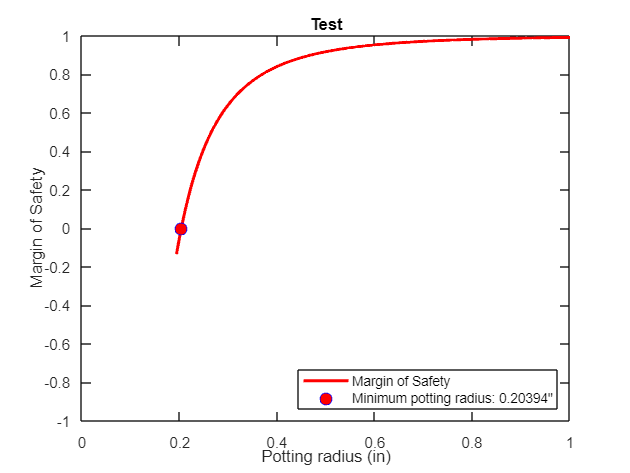


hold off;



a = 1.6

a = 1.6000

eta = 1/2 .* (1 + a./(5.*bp) .* 1./2)

eta =     0.9129    0.9108    0.9088    0.9068    0.9048    0.9028    0.9009    0.8989    0.8970    0.8951    0.8932    0.8913    0.8895    0.8877    0.8859    0.8841    0.8823    0.8805    0.8788    0.8770    0.8753    0.8736    0.8719    0.8703    0.8686    0.8670    0.8653    0.8637    0.8621    0.8605    0.8590    0.8574    0.8559    0.8543    0.8528    0.8513    0.8498    0.8484    0.8469    0.8454    0.8440    0.8426    0.8412    0.8397    0.8384    0.8370    0.8356    0.8342    0.8329    0.8316


Pss_near = eta .* Pss_typ

Pss_near = 1.0e+03 *

    0.7901    0.7888    0.7875    0.7863    0.7850    0.7838    0.7826    0.7815    0.7803    0.7792    0.7781    0.7771    0.7760    0.7750    0.7740    0.7730    0.7720    0.7711    0.7701    0.7692    0.7683    0.7674    0.7666    0.7657    0.7649    0.7641    0.7633    0.7625    0.7618    0.7610    0.7603    0.7596    0.7589    0.7582    0.7575    0.7569    0.7562    0.7556    0.7550    0.7544    0.7538    0.7532    0.7527    0.7521    0.7516    0.7511    0.7506    0.7501    0.7496    0.7491



plot(bp,Pss_typ*0.004448*2,'LineWidth',1,'Color','r'); % Pss converted lb to kN
xlabel('Potting radius (in)','FontWeight','bold');
ylabel('Failure Load (kN)','FontWeight','bold');
xlim([0 1]);
ylim([0 22])
ax = gca;
ax.FontName = 'Times New Roman'

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 22]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


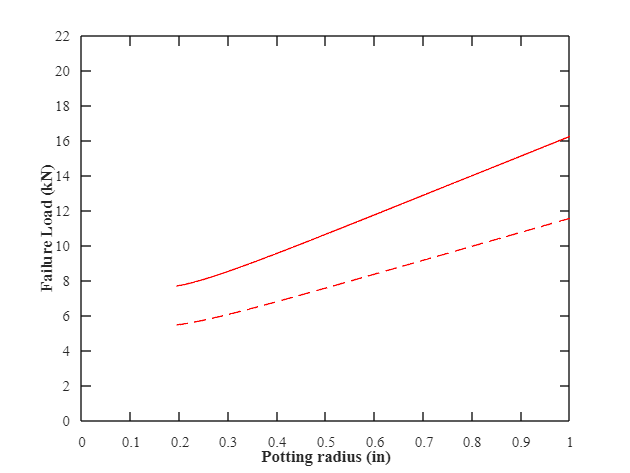

hold on;

plot(bp,Pss_min*0.004448*2,'LineWidth',1,'Color','r','LineStyle','--');

%%% THIS SHIT IS FOR DESIGN PLOTS
data = readtable("data for plots.xlsx");

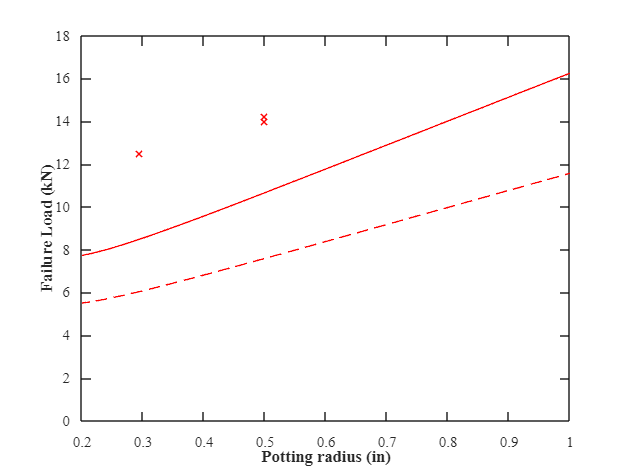


coreMask57 = data.CoreDensity_pcf_ == 5.7;
coreMask61 = data.CoreDensity_pcf_ == 6.1;

pr57 = data.PottingRadius_in_(coreMask57);
%pr57 = pr57(1);
pr61 = data.PottingRadius_in_(coreMask61);

actual57 = data.ActualYieldStrength_kN_(coreMask57);
%actual57 = actual57(1);
actual61 = data.ActualYieldStrength_kN_(coreMask61);

min57 = data.ExpectedMinimumStrength_kN_(coreMask57);
min61 = data.ExpectedMinimumStrength_kN_(coreMask61);

typ57 = data.ExpectedAvgStrength_kN_(coreMask57);
typ61 = data.ExpectedAvgStrength_kN_(coreMask61);

%scatter(pr61,typ61,'MarkerEdgeColor','red','LineWidth',0.8);
%hold on;
%scatter(pr61,min61);
scatter(pr61,actual61,'Marker','x','LineWidth',1,'MarkerEdgeColor','red')
xlabel('Potting radius (in)','FontWeight','bold');
ylabel('Failure Load (kN)','FontWeight','bold')
ax = gca;
ax.FontName = 'Times New Roman';
xlim([0.2 1]);
ylim([0 18]);


%%% THIS SHIT IS FOR DESIGN PLOTS
% CORE PROPERTIES - 5.7 pcf hexcel core
%clear;
P_kN = 15;
Q=0;
M=0;
P = P_kN / 224.8; % normal (tensile or compressive) force (lb)
Gc = 12833; % effective shear modulus (psi)
Sc = 3/16; % core cell size (in)
c = 0.75; % core height (in)
t0 = 0.002; % core foil thickness (in)
%Twcrit = 244; % minimum core shear strength (psi)
Twcrit_typ = 300; % typical core shear strength (psi)
Twcrit_min =244

Twcrit_min = 244


T0crit = 24000; % core material shear strength (psi) - Al 5052-H38 per ASM Matweb (Hexcel is H39)

% FACE SHEET PROPERTIES - from Aidan's, validate with SES
f = 0.055; % face sheet thickness (in)
vf = 0.3; % poisson's ratio = sqrt(vxy*vyx)
Ef = 5.77*10^6; % young's modulus (psi) = sqrt(Ex*Ey)
Sigma_fy = 14000; % interlaminar shear strength (psi)

% DEFINE INSERT RADIUS RANGE
bi = linspace(0.15,5,5000); % insert radius (in)
bp = bi+0.35*Sc; % real potting radius (in)

beta = c/f; % [C.2-9]
alpha = 1/f * sqrt(Gc/Ef*12*(1-vf^2)*(1+beta/2)); % [C.2-10]
t_nom = P ./ 2*pi.*bp.*c; % [C.2-13]
%K = bp./r * 
%t_r = t_nom .* C_star .* K;
C_star = beta / (beta+1); % [C.2-14];

r_tmax = bp./(1-exp(-.931714.*(alpha.*bp).^.262866)); % [C.2-16]
K_max = bp./r_tmax.*(1-sqrt(r_tmax./bp).*exp(alpha.*(bp-r_tmax))); % [C.2-6]

Pcrit_typ = (2.*pi.*bp.*c.*Twcrit_typ)./(C_star.*K_max); % [C.2-17] valid for tensile and compressive loads
%Pss = 0.89 .* Pcrit; % minimum insert capability 
Pcrit_min = (2.*pi.*bp.*c.*Twcrit_min)./(C_star.*K_max)

Pcrit_min = 1.0e+03 *

    0.8206    0.8216    0.8225    0.8235    0.8245    0.8254    0.8264    0.8274    0.8283    0.8293    0.8303    0.8313    0.8323    0.8333    0.8343    0.8353    0.8363    0.8373    0.8384    0.8394    0.8404    0.8414    0.8425    0.8435    0.8445    0.8456    0.8466    0.8477    0.8487    0.8498    0.8508    0.8519    0.8530    0.8540    0.8551    0.8562    0.8572    0.8583    0.8594    0.8605    0.8616    0.8627    0.8637    0.8648    0.8659    0.8670    0.8681    0.8692    0.8703    0.8714


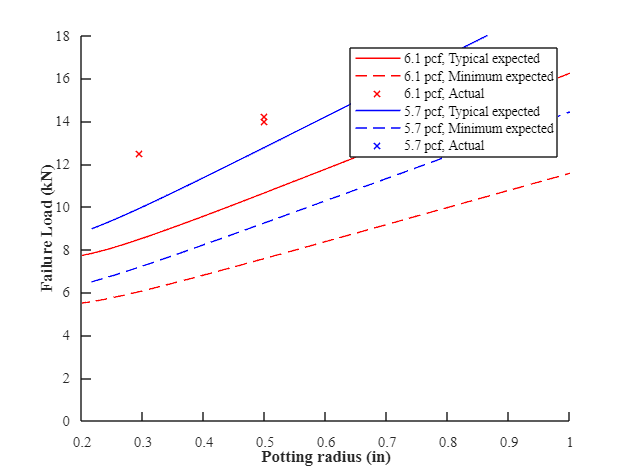

%Pss = 0.89 .* Pcrit; % minimum insert capability 
Pss_typ = Pcrit_typ; % typical insert capability
Pss_min = Pcrit_min * 0.89;

Qss = 8 * bp.^2 * Twcrit_typ + 2.*f*bp.*Sigma_fy; % [14.2-1] for bp < .433"

Mss = Pcrit_typ .* bi;

MS =-((Q./Qss).^2 + (P./Pss_typ).^2+ (M./Mss).^2 - 1); % Margin of Safety
plot(bp,Pss_typ*0.004448*2,'LineWidth',1,'Color','b'); % Pss converted lb to kN
hold on;
plot(bp,Pss_min*0.004448*2,'LineWidth',1,'Color','b','LineStyle','--');

box off;

%scatter(pr57,typ57,'MarkerEdgeColor','blue','LineWidth',0.8);
%scatter(pr57,min57);
scatter(pr57,actual57,'Marker','x','LineWidth',1,'MarkerEdgeColor','blue')
xlabel('Potting radius (in)','FontWeight','bold');
ylabel('Failure Load (kN)','FontWeight','bold')
ax = gca;
ax.FontName = 'Times New Roman';
xlim([0.2 1]);
ylim([0 18]);
%hold off
legend('6.1 pcf, Typical expected','6.1 pcf, Minimum expected', '6.1 pcf, Actual','5.7 pcf, Typical expected','5.7 pcf, Minimum expected','5.7 pcf, Actual')


%}

**POTTING RADIUS CALCULATED FOR TABULATED LOADS**

clear;
close all;

% Table of maximum insert loadcases
loads = readtable("MR26_FLCA_Fore.xlsx","VariableNamingRule","preserve");

for i = 1:1:width(loads)-1
for j = 1:1:2

SF = 2; % safety factor applied to loads. Above 1.5 is representative of normal driving.

% Friction compensation section - each insert is assumed to take:
% Design shear load = Bracket shear load - Max friction with bolt preload
bolt_preload = 2125.8; % lb, 75% of proof load assuming 160 ksi (min strength)
mu = 0.2; % Al bracket on Carbon, from Gabe's empirical test
max_friction = 2*bolt_preload*mu; % lb, for entire bracket (2 bolts)

% Definition of design loads from table
P = SF*loads{1+j,i+1}; % transverse / normal force (lb)
Q = SF*loads{1,i+1} - max_friction; % in-plane / shear force (lb)
if Q < 0
    Q = 0; % if max friction > shear force, shear force = 0 at insert.
end
M = SF*loads{4,i+1};    % bending moment (lb-in) - only nonzero for FLCA bracket

% CORE PROPERTIES - 6.1 pcf hexcel core
Gc = 13667; % effective shear modulus (psi)
Sc = 0.125; % core cell size (in)
c = 0.75; % core height (in)
t0 = 0.0015; % core foil thickness (in)
Twcrit_typ = 272; % minimum core shear strength (psi)
T0crit = 24000; % core material shear strength (psi) - Al 5052-H38 per ASM Matweb (Hexcel is H39)

% FACE SHEET PROPERTIES - from Aidan's, validate with SES
f = 0.055; % face sheet thickness (in)
vf = 0.3; % poisson's ratio = sqrt(vxy*vyx)
Ef = 4.33*10^6; % young's modulus (psi) = sqrt(Ex*Ey)
Sigma_fy = 14000; % interlaminar shear strength (psi)

% DEFINE INSERT RADIUS RANGE
bi = linspace(0.15,4,5000); % insert radius (in) - under 0.15 is unstable
bp = bi+0.35*Sc; % real potting radius (in)
beta = c/f; % [C.2-9]
alpha = 1/f * sqrt(Gc/Ef*12*(1-vf^2)*(1+beta/2)); % [C.2-10]
t_nom = P ./ 2*pi.*bp.*c; % [C.2-13]
C_star = beta / (beta+1); % [C.2-14];
r_tmax = bp./(1-exp(-.931714.*(alpha.*bp).^.262866)); % [C.2-16]
K_max = bp./r_tmax.*(1-sqrt(r_tmax./bp).*exp(alpha.*(bp-r_tmax))); % [C.2-6]
Pcrit_typ = (2.*pi.*bp.*c.*Twcrit_typ)./(C_star.*K_max); % [C.2-17] valid for tensile and compressive loads
Pss_typ = 0.89 .* Pcrit_typ; % minimum insert capability, to be conservative
Qss = 8 * bp.^2 * Twcrit_typ + 2.*f*bp.*Sigma_fy; % [14.2-1] for bp < .433"
Mss = Pcrit_typ .* bi;
MS =-((Q./Qss).^2 + (P./Pss_typ).^2+ (M./Mss).^2 - 1); % Margin of Safety

% DETERMINE MINIMUM INSERT & POTTING RADIUS, AT WHICH SAFETY MARGIN = 0
bi_soln = bi(MS>=-0.05 & MS<=0.05);
bi_soln = mean(bi_soln);
bp_soln(j,i) = bi_soln+0.35*Sc; 
if isnan(bp_soln(j,i))
    bp_soln(j,i) = 0.25;
else if bp_soln(j,i) < 0.25
        bp_soln(j,i) = .25;
end
end
end
link_names{i} = string(loads.Properties.VariableNames{i+1});
end

potting_rad_table = [link_names; num2cell(bp_soln)]

potting_rad_table = 3×11 cell array
    {["FUCA fore"]}    {["FUCA aft"]}    {["FLCA fore"]}    {["FLCA aft"]}    {["RUCA fore"]}    {["RUCA aft"]}    {["RLCA fore"]}    {["RLCA aft"]}    {["Rear Toe Link"]}    {["Front Inboard"]}    {["Rear Inboard"]}
    {[     0.2500]}    {[    0.2500]}    {[     0.8168]}    {[    0.2500]}    {[     0.2500]}    {[    0.2500]}    {[     0.2500]}    {[    0.2500]}    {[         0.2500]}    {[         0.2500]}    {[        0.2500]}
    {[     0.2500]}    {[    0.2500]}    {[     0.8168]}    {[    0.2500]}    {[     0.2500]}    {[    0.2500]}    {[     0.2500]}    {[    0.2500]}    {[         0.2500]}    {[         0.2500]}    {[        0.2500]}
